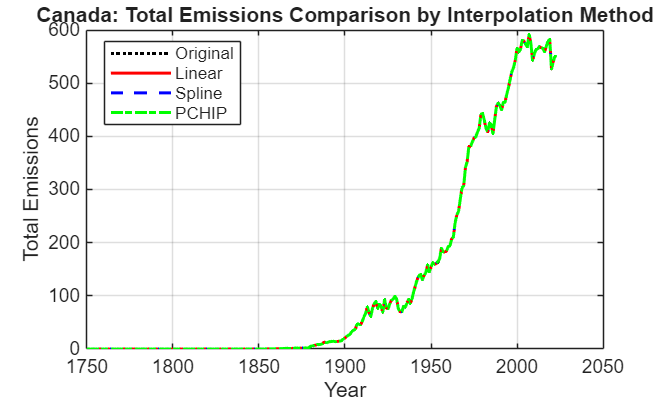

canadaData1 = 274×13 table
     Country      ISO 3166-1 alpha-3    UN M49    Year    Total    Coal    Oil    Gas    Cement    Flaring    Other    Per Capita    Var13
    __________    __________________    ______    ____    _____    ____    ___    ___    ______    _______    _____    __________    _____

    {'Canada'}         {'CAN'}           124      1750      0      NaN     NaN    NaN     NaN         0        NaN        NaN         NaN 
    {'Canada'}         {'CAN'}           124      1751      0      NaN     NaN    NaN     NaN         0        Na

% Read the Excel file
data = readtable('carbon_emissions_full_data.xlsx', 'VariableNamingRule', 'preserve');

% Filter only Canada rows
canadaData = data(strcmp(data.Country,'Canada'), :);

% Extract Flaring column
flaring = canadaData.Flaring;

% Find the first and last real measurements (>0)
firstNonZero = find(flaring > 0, 1, 'first');   % first actual value
lastNonZero  = find(flaring > 0, 1, 'last');    % last actual value

% Step 1: Set all leading values (before first measurement) to 0
flaring(1:firstNonZero-1) = 0;

% Step 2: Set internal zeros (between first and last measurement) to NaN
internalIdx = firstNonZero:lastNonZero;
flaring(internalIdx(flaring(internalIdx)==0)) = NaN;

% Update the table
canadaData.Flaring = flaring;

vars = {'Coal','Oil','Gas','Cement','Flaring','Other'};
canadaData1.Total = sum(canadaData1{:,vars},2,'omitnan');
canadaData2.Total = sum(canadaData2{:,vars},2,'omitnan');
canadaData3.Total = sum(canadaData3{:,vars},2,'omitnan');

figure;
plot(canadaData.Year, canadaData.Total, 'k:', 'LineWidth', 1.5); hold on; 
plot(canadaData1.Year, canadaData1.Total, 'r-', 'LineWidth', 1.5);
plot(canadaData2.Year, canadaData2.Total, 'b--', 'LineWidth', 1.5);
plot(canadaData3.Year, canadaData3.Total, 'g-.', 'LineWidth', 1.5);
legend({'Original', 'Linear','Spline','PCHIP'}, 'Location', 'best');
xlabel('Year');
ylabel('Total Emissions');
title('Canada: Total Emissions Comparison by Interpolation Method');
grid on;